# Star Detection Testing

I = imread('calibrated_raw/20250321T192416_651_StackInput.tiff');

SURF

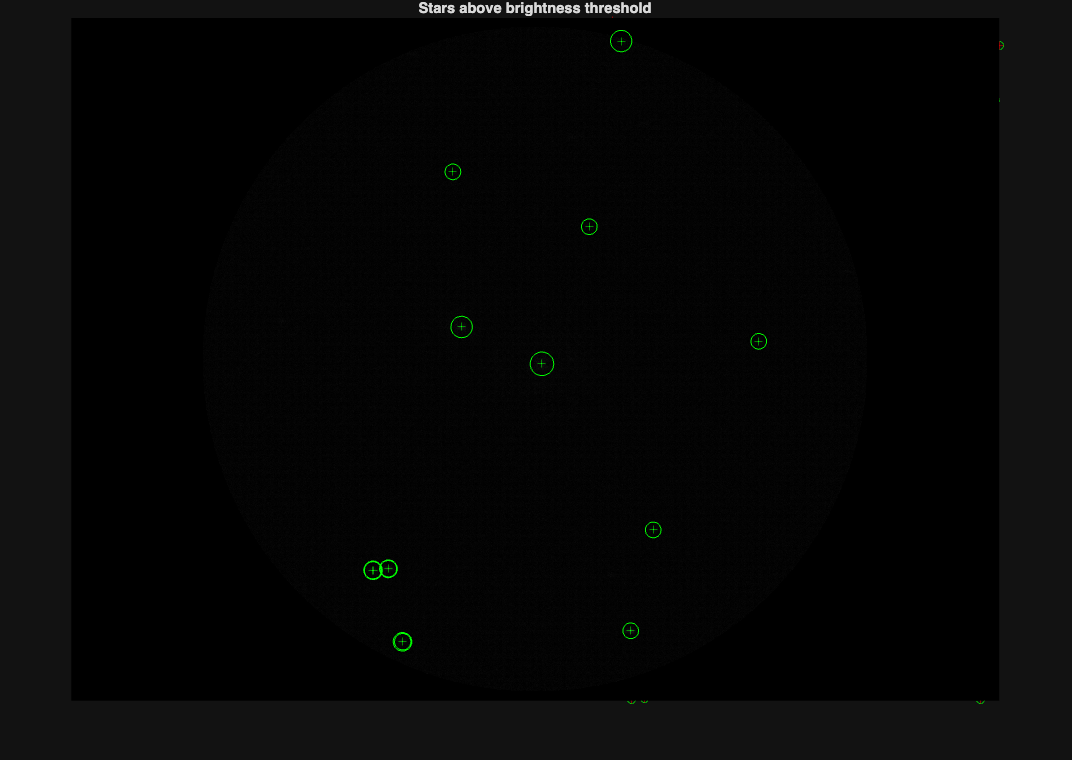

I_smooth = imgaussfilt(I, 1);        % sigma = 1 pixel
I_bgsub = I_smooth - imgaussfilt(I_smooth, 10);  % remove large-scale background

points = detectSURFFeatures(I_bgsub, 'MetricThreshold', 10);
imshow(I); hold on;
plot(points.selectStrongest(200));

Region

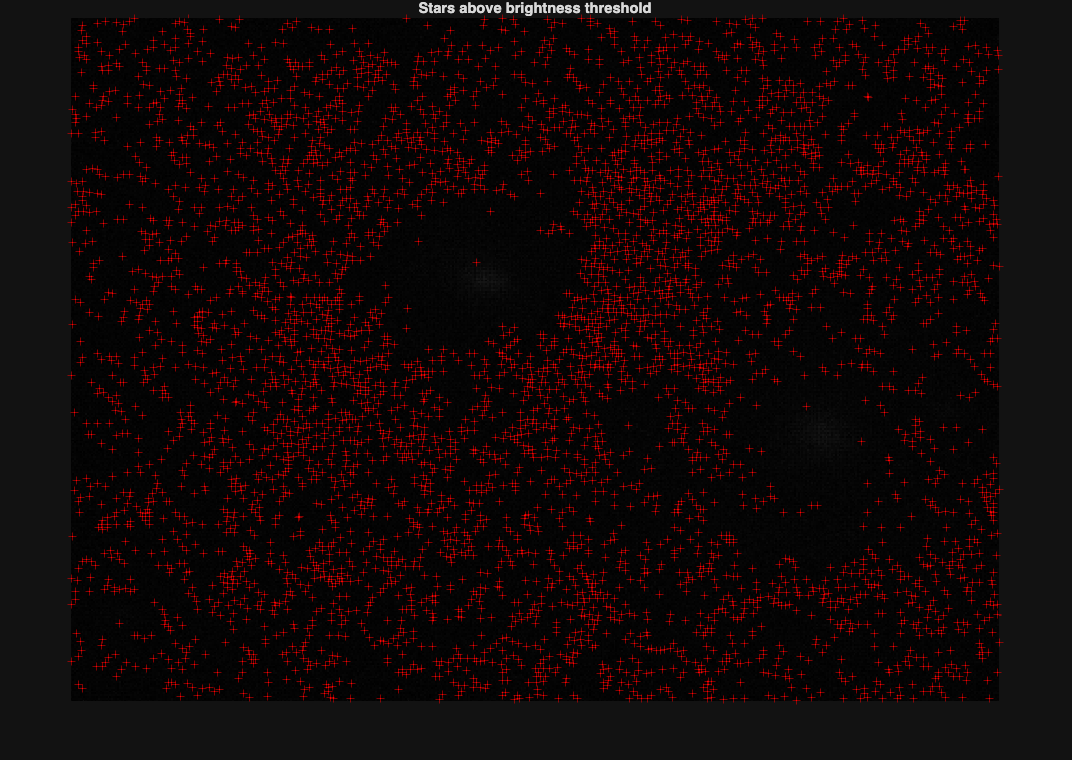

% bw = imbinarize(I, 'adaptive', 'ForegroundPolarity','bright','Sensitivity',0.5);
% stats = regionprops(bw, 'Centroid', 'Area');
% centroids = cat(1, stats.Centroid);
% 
% imshow(I); hold on;
% plot(centroids(:,1), centroids(:,2), 'r+');

Local Maxima

points = get_star_tracking_points(I, .5);


imshow(I, []); hold on;
if true
    plot(points(:,1), points(:,2), 'r+');
    title('Stars above brightness threshold');
end

Detect Dark

dark = imread('darkframe.tiff');
dark_points = get_star_tracking_points(dark);


imshow(dark, []); hold on;
if true
    plot(dark_points(:,1), dark_points(:,2), 'r+');
    title('Darkframe');
end

Overlay 

imshow(I, []); hold on;
if true
    plot(points(:,1), points(:,2), 'r+');
    plot(dark_points(:,1), dark_points(:,2), 'go');
    title('Stars with overlay of dark plot');
end

Remove Dark Overlay

dark = imread('darkframe.tiff');
points = get_star_tracking_points(I-dark);


imshow(I-dark, []); hold on;
if true
    plot(points(:,1), points(:,2), 'r+');
    plot(dark_points(:,1), dark_points(:,2), 'go');
    title('Stars - Dark');
end